currentFolder = 'D:\chenzhou-OneDrive\OneDrive\Study\Sophomore\Signals and Systems\lab\project2'

currentFolder = 'D:\chenzhou-OneDrive\OneDrive\Study\Sophomore\Signals and Systems\lab\project2'

addpath(genpath(currentFolder));
idx_start_time =1;
data = load(sprintf('./data/data_%d.mat',idx_start_time))

data = 包含以下字段的 struct :
    cur_time: 0
    duration: 0.5000
         f_c: 2.1230e+09
         f_s: 25000000
     seq_ref: [-2.0000e-07 + 1.0000e-07i 1.0000e-07 + 0.0000e+00i -1.0000e-07 + 0.0000e+00i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0000 + 0.0000i 0.0000 + 0.0000i 1.0000e-07 + 0.0000e+00i -1.0000e-07 + 0.0000e+00i … ]
     seq_sur: [1.0000e-06 - 1.7000e-06i 0.0000e+00 + 7.0000e-07i -1.0000e-07 - 5.0000e-07i 1.0000e-07 + 5.0000e-07i 0.0000e+00 - 3.0000e-07i 1.0000e-07 + 3.0000e-07i -1.0000e-07 - 3.0000e-07i 1.0000e-07 + 2.0000e-07i -1.0000e-07 - 2.0000e-07i … ]


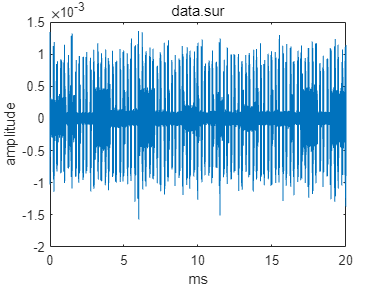

sur = data.seq_sur;
ref = data.seq_ref;
N = length(data.seq_sur);
plot_num = 0.02*data.f_s;
sur_plot = data.seq_sur(1,1:plot_num);
ref_plot = data.seq_ref(1,1:plot_num);
figure
plot(linspace(0,20,plot_num),real(sur_plot));xlabel('ms');ylabel('amplitude'),title('data.sur')

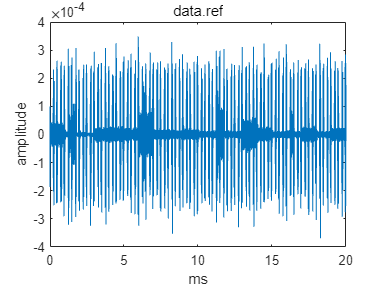

plot(linspace(0,20,plot_num),real(ref_plot));xlabel('ms');ylabel('amplitude'),title('data.ref')

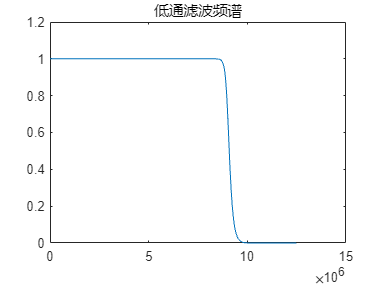


f_band = 9e6;
[b,a] = butter(20,f_band/(data.f_s/2));
[h,f] = freqz(b,a,512,data.f_s);
figure
plot(f,abs(h)),title('低通滤波频谱');

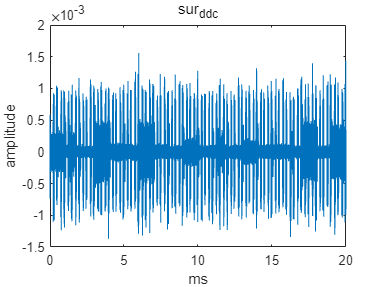


f_ddc = -3e6;
sur_ddc = sur.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
ref_ddc = ref.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
sur_plot = sur_ddc(1,1:plot_num);
ref_plot = ref_ddc(1,1:plot_num);
figure
plot(linspace(0,20,plot_num),real(sur_plot));xlabel('ms');ylabel('amplitude'),title('sur_{ddc}')

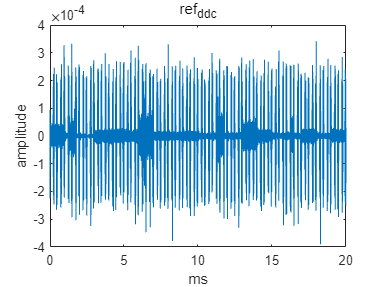

plot(linspace(0,20,plot_num),real(ref_plot));xlabel('ms');ylabel('amplitude'),title('ref_{ddc}')

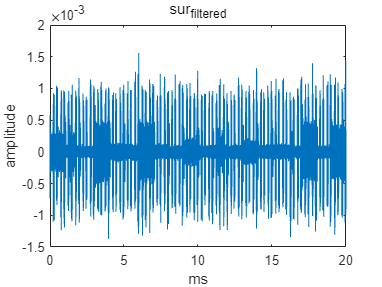



sur_out = filter(b,a,sur_ddc);
ref_out = filter(b,a,ref_ddc);
sur_plot = sur_ddc(1,1:plot_num);
ref_plot = ref_ddc(1,1:plot_num);
figure
plot(linspace(0,20,plot_num),real(sur_plot));xlabel('ms');ylabel('amplitude'),title('sur_{filtered}')

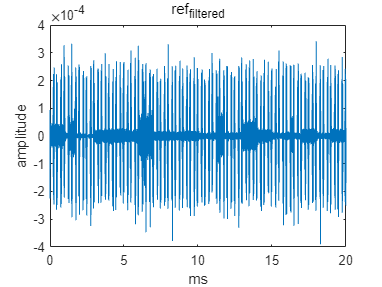

plot(linspace(0,20,plot_num),real(ref_plot));xlabel('ms');ylabel('amplitude'),title('ref_{filtered}')

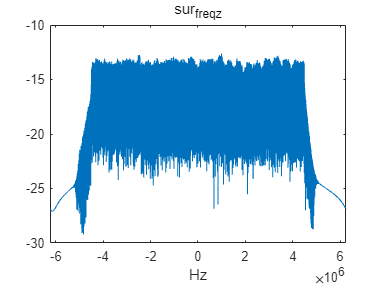



sur = fftshift(fft(sur_out)./N);
ref = fftshift(fft(ref_out)./N);
figure
plot(-N/2:N-N/2-1,log(abs(sur))),xlabel('Hz'),title('sur_{freqz}')

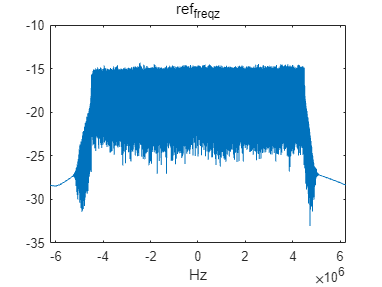

plot(-N/2:N-N/2-1,log(abs(ref))),xlabel('Hz'),title('ref_{freqz}')

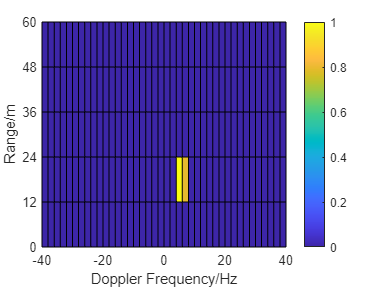

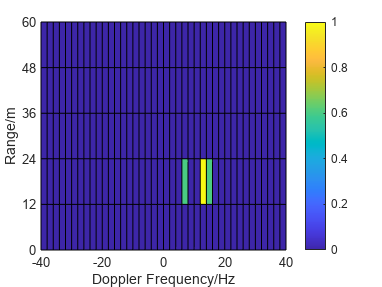

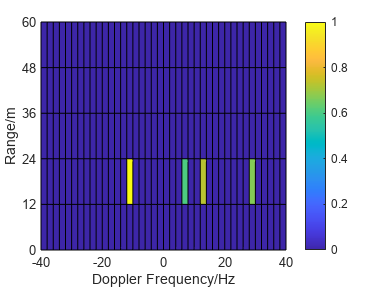

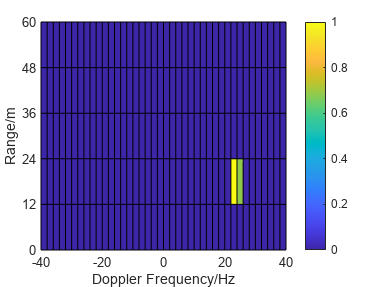

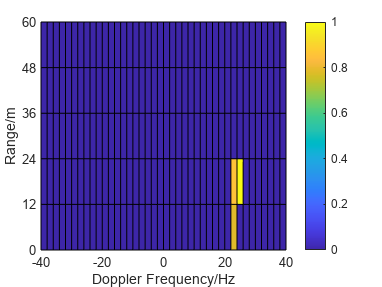

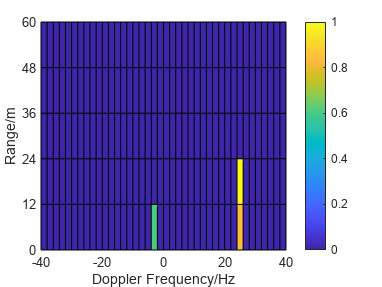

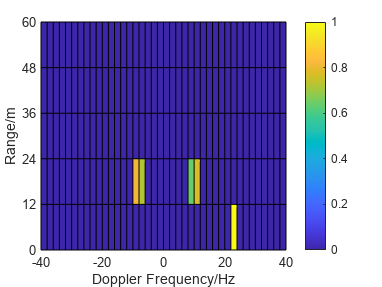

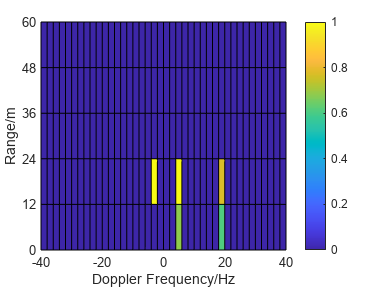


n_tau = 0:5;
fd = -40:2:40;
for n = 1:20
    data = load(sprintf('./data/data_%d.mat',n));
    sur = data.seq_sur;
    ref = data.seq_ref;
    f_band = 9e6;
    [b,a] = butter(20,f_band/(data.f_s/2));
    [h,f] = freqz(b,a,512,data.f_s);
    f_ddc = -3e6;
    sur_ddc = sur.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
    ref_ddc = ref.*exp(-1i*2*pi*f_ddc*(0:N-1)/data.f_s);
    sur_out = filter(b,a,sur_ddc);
    ref_out = filter(b,a,ref_ddc);
    results = zeros([length(n_tau), length(fd)]);
    for i = 1:length(n_tau)
        for j = 1:length(fd)
            ref_r = [zeros(1,i - 1), ref_out];
            ref_r = ref_r(1:125e5);
            results(i,j) = ambiguity(sur_out, ref_r, fd(j));
        end
    end
    results = abs(results);
    n_tau = 0:12:60;
    [x,y] = meshgrid(fd, n_tau);
    results = results/max(max(results));
    results(results < 0.6) = 0;
    figure;
    surf(x,y,results);
    view(2);
    xlabel('Doppler Frequency/Hz'), ylabel('Range/m');
    colorbar;
    yticks(0:12:60);yticklabels({'0','12','24','36','48','60'});
    [r,c] = find(results==max(max(results)));
end

function cor = ambiguity(sur, ref, f)
    Ts = 1/25000000;
    nn = 1:125e5;
    cor = sum(conj(ref).*sur.*exp(-1j*2*pi*nn*Ts*f));
end